clear
M = load('StudentData/FeaturesM');
T = load('StudentData/FeaturesT');

Training data

for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation];
end

Testing and validation set

Indices = randperm(300); % Here we randomly permute data indices

for sample = 1:150
TestingDataClass0(:,sample) = ...
[M.Data(300+Indices(sample)).Normal.Area,...
M.Data(300+ Indices(sample)).Normal.Orientation];
TestingDataClass1(:,sample) = ...
[T.Data(300+Indices(sample)).Normal.Area,...
T.Data(300+Indices(sample)).Normal.Orientation];
end
for sample = 1:150
FinalTestClass0(:,sample) = ...
[M.Data(300+Indices(sample)).Normal.Area,...
M.Data(300+Indices(sample)).Normal.Orientation];
FinalTestClass1(:,sample) = ...
[T.Data(300+Indices(sample)).Normal.Area,...
T.Data(300+Indices(sample)).Normal.Orientation];
end

Normalization

Means = abs(mean([TrainingDataClass0,TrainingDataClass1]'));

TrainingDataClass0 = TrainingDataClass0./Means';
TrainingDataClass1 = TrainingDataClass1./Means';
TestingDataClass0=TestingDataClass0./Means';
TestingDataClass1=TestingDataClass1./Means';

Combination of net sizes

clear config
counter=0;
for i=1:10
    for k=1:10
        for n=1:10
            if i+k+n==12
            counter=counter+1;
            config(counter,:)=[i,k,n];
            end
        end
    end
end


repetitions=10;

TargetTrain = [ones(1,300),zeros(1,300)];
TrainingData = [TrainingDataClass0,TrainingDataClass1];

TestSerie=0;


for nettype=1:length(config)
NetworkSize = config(nettype,:).*2; % Number of neurons in all the hidden layers

TestSerie=TestSerie+1;

for Test = 1:repetitions
OurNet = newff(TrainingData,TargetTrain,NetworkSize); % Net initialization
OurNet.TrainParam.time = 20; % Max time allowed
OurNet = train(OurNet,TrainingData,TargetTrain);
Results0 = sim(OurNet,TestingDataClass0);
Results1 = sim(OurNet,TestingDataClass1);
ErrorsA(Test,TestSerie) = sum([Results0<0.5]);
ErrorsD(Test,TestSerie) = sum([Results1>=0.5]);
ErrorSum(Test,TestSerie) = ErrorsD(Test,TestSerie)+ErrorsA(Test,TestSerie);
end
end


Performance statistic

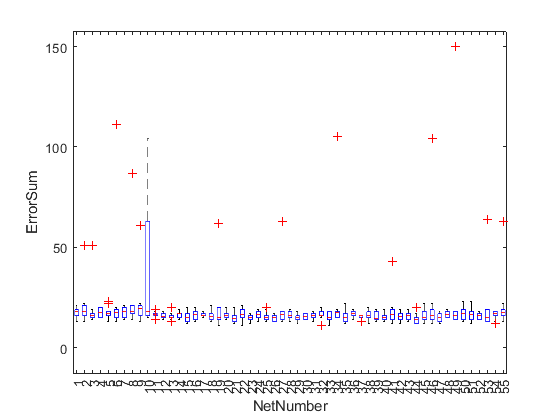

figure; boxplot(ErrorSum); ylabel('ErrorSum'); xlabel('NetNumber');

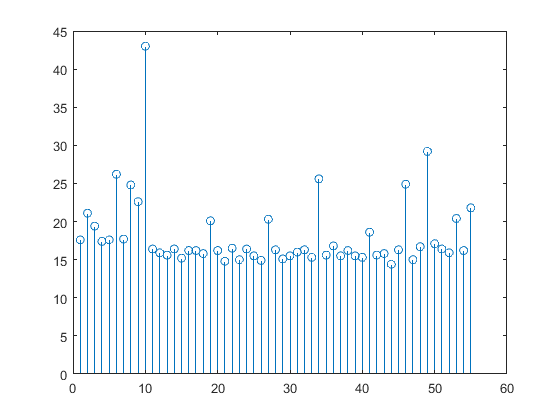

[m,n]=size(ErrorSum);
for i=1:n
    meanerror(i)=mean(ErrorSum(:,i));
end
stem(meanerror)

[val,loc]=min(meanerror)

val = 14.4000

loc = 44

bestconf=config(loc,:)

bestconf =      6     4     2


save loc
save val
save bestconf
save ErrorSum